Задаём параметры источника напряжения

source.voltage = 220;
source.freq = 50;

Задаём параметры трансформатора

transparam.power = 300 * 10^3;
transparam.volt1wing = 220;
K_T = 1;
transparam.volt2wing = transparam.volt1wing * K_T;

Задаём параметры нагрузки

load.Res = 1;
load.Ind = load.Res * 0.01;

Подготавливаем массивы для снятия параметров измерений в таблицу

r_l = [];
i_l = [];
I_n = [];
U_n = [];
I_1max = [];
Phi_1max = [];
U_VDmax = [];
I_VDmax = [];
U_1max = source.voltage * ones(1, 10);
f_1 = source.freq * ones(1, 10);
S_1 = [];
P_1 = [];
P_n = [];

Запускаем модель 10 раз с шагом изменения сопротивления 1 Ом, добавляем значения в вышесозданные массивы каждую итерацию, рассчитываем параметры по формулам:


$$S_{1}(1) = \frac {U_{1max} \cdot I_{1max}}  {2} $$



$$P_{1}(1) = S_{1}(1) \cdot cos(\phi)$$



$$P_н = U_н \cdot I_н$$


for i = 1:1:10
    load.Res = i;
    load.Ind = load.Res * 0.01;
    sim("lr1.slx");
    I_n(end+1) = ans.loadCurrent(end, 1);
    U_n(end+1) = ans.loadVoltage(end, 1);
    I_1max(end+1) = ans.sourceCurrent(end, 1);
    Phi_1max(end+1) = ans.sourcePhase(end, 1);
    r_l(end+1) = load.Res;
    i_l(end+1) = load.Ind;
    U_VDmax(end+1) = max(ans.VoltageVDmax);
    I_VDmax(end+1) = max(ans.CurrentVDmax);
    S_1(end+1) = U_1max(i) * I_1max(i) / 2;
    P_1(end+1) = S_1(i)*cos(Phi_1max(i)*pi/180);
    P_n(end+1) = U_n(i) * I_n(i);
end

Заносим результаты моделирования в таблицу

T = table(U_1max.',f_1.', r_l.',i_l.',I_n.',U_n.',I_1max.',Phi_1max.', U_VDmax.', I_VDmax.', S_1.', P_1.', P_n.');
T.Properties.VariableNames = ["U1max", "f1", "Rн", "Lн", "Iн","Uн","I1max","phi1max", "U_VDmax", "I_VDmax", "S1", "P1", "Pн"]; %задание имени столбцов переменных
disp(T);

    U1max    f1    Rн     Lн       Iн        Uн      I1max     phi1max    U_VDmax     I_VDmax      S1        P1        Pн  
    _____    __    __    ____    ______    ______    ______    _______    ________    _______    ______    ______    ______

     220     50     1    0.01    133.15    133.15    173.51    -5.6756     0.14734    147.34      19086     18992     17728
     220     50     2    0.02     68.24    136.48    89.963     -5.425    0.075356    75.356       9896    9851.6    9313.5
     220     50     3    0.03     45.88    137.64    61.198  

Строим осциллограммы напряжения и тока диодов моста

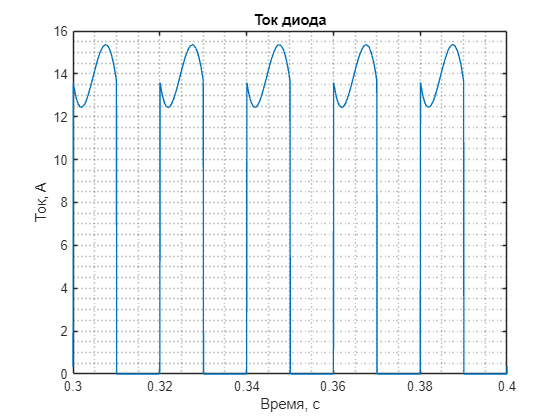

plot(ans.ScopeVD{1}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Напряжение, В');
title('Напряжение на диоде');
xlim([0.3 0.4]);

plot(ans.ScopeVD{2}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Ток, А');
title('Ток диода');
xlim([0.3 0.4]);

Строим осциллограммы тока питания, тока нагрузки и напряжения на нагрузке

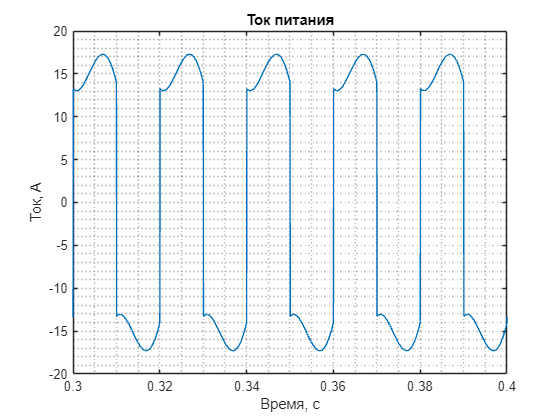

plot(ans.Scope{1}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Ток, А');
title('Ток питания');
xlim([0.3 0.4]);

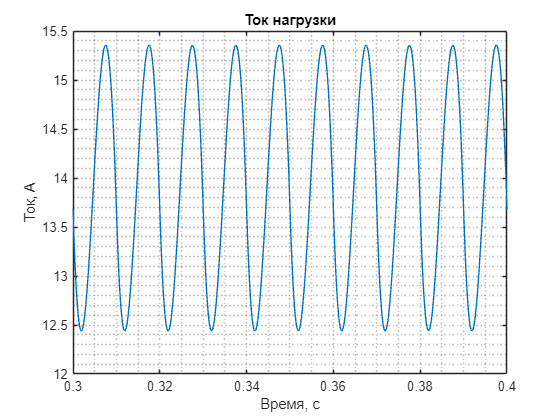

plot(ans.Scope{2}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Ток, А');
title('Ток нагрузки');
xlim([0.3 0.4]);

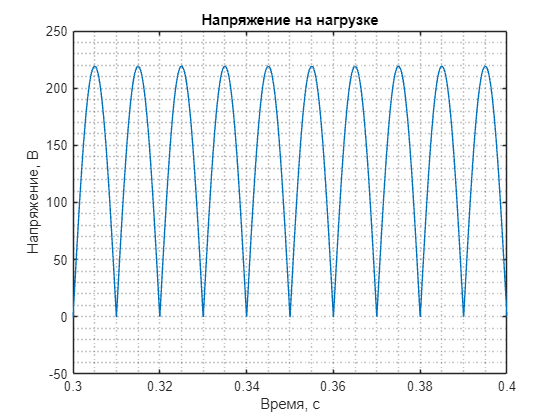

plot(ans.Scope{3}.Values);
grid("minor");
xlabel('Время, с');
ylabel('Напряжение, В');
title('Напряжение на нагрузке');
xlim([0.3 0.4]);